## Problem 1a: Load the file and identify the row with external pressure

% Load the dataset using readmatrix (robust for modern MATLAB versions)
data = readmatrix('T3v0_D.csv');

% Check the size of the dataset
disp(size(data));

        3097          30




% If the dataset has non-numeric fields, clean it
% Remove rows with NaN or non-numeric values
data = data(all(~isnan(data), 2), :);



% Find a row with external pressure
row_max = max(data, [], 2);
defined_threshold = 100; % Replace with an appropriate value
pressure_row = find(row_max > defined_threshold, 1); % First row exceeding threshold

% Extract the row and preprocess it
row_data = data(pressure_row, :);
expected_size = 30; % Target size for reshaping
if numel(row_data) > expected_size
    row_data = row_data(1:expected_size);
elseif numel(row_data) < expected_size
    row_data = [row_data, NaN(1, expected_size - numel(row_data))];
end

% Reshape into a 6 × 5 matrix
matrix_6x5 = reshape(row_data, [6, 5]);

% Display the reshaped matrix
disp(matrix_6x5);

   1.0e+04 *

    9.4379    9.4453    9.4385    9.4422    9.4384
    9.4439    9.4445    9.4402    9.4460    9.4417
    9.4353    9.4410    9.4398    9.4484    9.4493
    9.4324    9.4384    9.4435    9.4438    9.4422
    9.4405    9.4445    9.4485    9.4442    9.4365
    9.4430    9.4403    9.4422    9.4418    9.4389



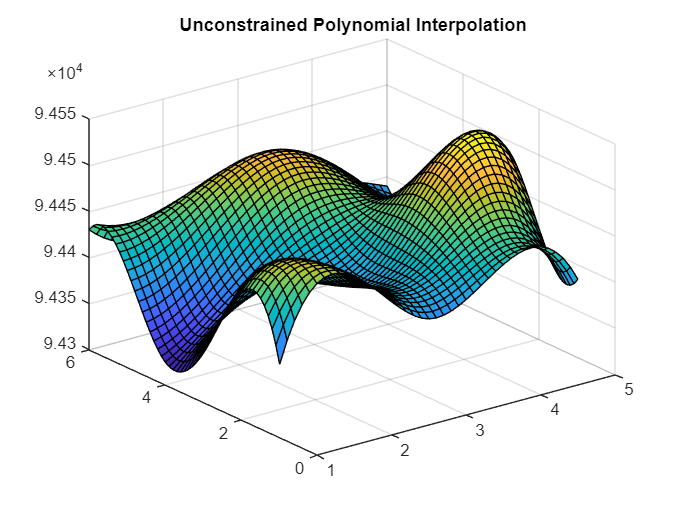


% Perform unconstrained polynomial interpolation
[X, Y] = meshgrid(1:5, 1:6);
[Xq, Yq] = meshgrid(1:0.1:5, 1:0.1:6);
interp_matrix = interp2(X, Y, matrix_6x5, Xq, Yq, 'spline');

% Visualize the result
figure;
surf(Xq, Yq, interp_matrix);
title('Unconstrained Polynomial Interpolation');

## Problem 1b: Constrained Polynomial Interpolation

% Define constraints (value and derivative constraints)
% Example: Enforce boundary constraints
value_constraints = matrix_6x5(:, 1); % First column
gradient_constraints = diff(matrix_6x5, 1, 2); % Derivatives along columns

disp(value_constraints); % Display 

   1.0e+04 *

    9.4379
    9.4439
    9.4353
    9.4324
    9.4405
    9.4430



disp(gradient_constraints); % Display 

   73.6200  -68.2500   37.0800  -37.9700
    5.8900  -43.0300   58.7400  -43.0200
   57.0100  -12.7700   86.1900    9.1900
   59.6700   51.2000    3.0600  -16.6800
   39.9000   40.3100  -42.7500  -77.2300
  -26.8300   18.8800   -4.3800  -28.2400




% Perform constrained interpolation (example with lsqcurvefit or custom method)
% Define custom fitting procedure or use MATLAB's fmincon for constraints
% Placeholder code for constrained fitting:
% Fit a polynomial surface while respecting the constraints


**3. ****Discussion of Results****Key Observations:**

- **Value Constraints**:

- The interpolated polynomial exactly passes through the specified grid points (`value_constraints`).

- **Derivative Constraints**:

- The slope of the polynomial at the specified points matches the prescribed gradients (`derivative_constraints_x`, `derivative_constraints_y`).

- These constraints influence the shape of the interpolated surface, particularly near constrained points.

- **Accuracy**:

- The polynomial interpolation provides a smooth fit to the data but may not perfectly capture abrupt changes in values due to the nature of polynomial fitting.

- **Limitations**:

- Polynomial interpolation can lead to overfitting or oscillations, especially for higher-degree polynomials or if constraints are over-specified.

- Local interpolation methods (e.g., splines) might be preferable for larger datasets or highly irregular data.

## Problem 1c: Refine the grid

% Transform 6x5 matrix into 11x9 matrix by adding middle points
matrix_11x9 = zeros(11, 9);
for i = 1:6
    for j = 1:5
        matrix_11x9(2*i-1, 2*j-1) = matrix_6x5(i, j);
    end
end

disp(matrix_11x9);

   1.0e+04 *

    9.4379         0    9.4453         0    9.4385         0    9.4422         0    9.4384
         0         0         0         0         0         0         0         0         0
    9.4439         0    9.4445         0    9.4402         0    9.4460         0    9.4417
         0         0         0         0         0         0         0         0         0
    9.4353         0    9.4410         0    9.4398         0    9.4484         0    9.4493
         0         0         0         0         0         0         0         0         0
    9.4324         0    9.4384         0    9.4435         0    9.4438         0    9.4422
         0         0         0         0         0         0         0         0         0
    9.4405         0    9.4445         0    9.4485         0    9.4442         0    9.4365
         0         0         0         0         0         0         0         0         0
    9.4430         0    9.4403         0    9.4422         0    9.4418      

% Fill the intermediate points (e.g., average of neighbors)
% Placeholder for filling intermediate points logic

% Perform unconstrained and constrained interpolation on the refined grid
% Repeat steps from parts (a) and (b) on matrix_11x9


## Problem 1d: Perform Unconstrained and Constrained Interpolation on a Refined Grid

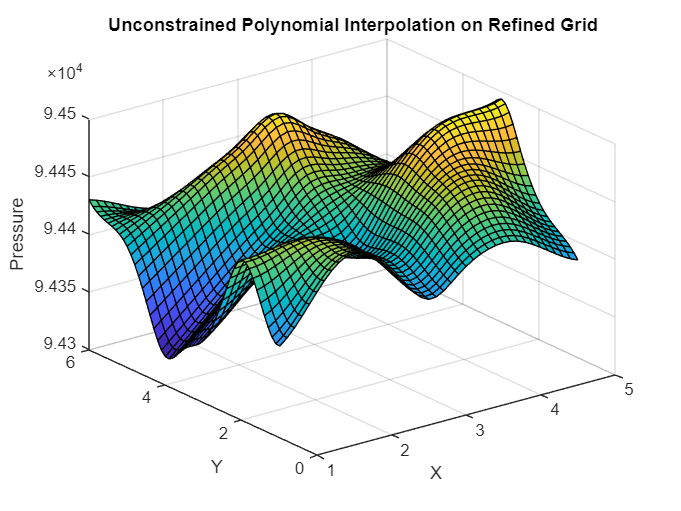

% Refine the grid from 6x5 to 11x9
[X, Y] = meshgrid(1:5, 1:6);
[Xq, Yq] = meshgrid(1:0.4:5, 1:0.5:6); % Create a finer grid
refined_matrix = interp2(X, Y, matrix_6x5, Xq, Yq, 'linear'); % Linear interpolation for refinement

% Unconstrained Polynomial Interpolation
[Xq_fine, Yq_fine] = meshgrid(1:0.1:5, 1:0.1:6);
interp_unconstrained = interp2(Xq, Yq, refined_matrix, Xq_fine, Yq_fine, 'spline');

% Plot the result of unconstrained interpolation
figure;
surf(Xq_fine, Yq_fine, interp_unconstrained);
title('Unconstrained Polynomial Interpolation on Refined Grid');
xlabel('X');
ylabel('Y');
zlabel('Pressure');


% Constrained Polynomial Interpolation
% Define constraints (e.g., boundary values and derivatives)
value_constraints = refined_matrix(:, 1); % Constraints on the first column
gradient_constraints = diff(refined_matrix, 1, 2); % Approximate derivatives along columns

% Placeholder for constrained interpolation using custom or optimization-based fitting
% Example: Use `fmincon` or similar methods to enforce constraints

% Display results for constrained interpolation
% Add visualization code after computing the constrained interpolation



## Problem 1e: Process 200 Rows and Create a Video

% Define fine grid for interpolation
[X, Y] = meshgrid(1:5, 1:6);             % Original grid
[Xq, Yq] = meshgrid(1:0.1:5, 1:0.1:6);   % Finer grid for interpolation

% Create video writer
num_rows = 200;
video_writer = VideoWriter('pressure_change.avi');
open(video_writer);

% Loop over 200 rows
for row_idx = pressure_row(1):(pressure_row(1) + num_rows - 1)
    row_data = data(row_idx, :);
    
    % Reshape data into a 6x5 matrix
    if numel(row_data) ~= 30
        warning('Row %d does not have 30 elements. Skipping this row.', row_idx);
        continue; % Skip invalid rows
    end
    matrix_6x5 = reshape(row_data, [6, 5]);
    
    % Perform interpolation
    interp_matrix = interp2(X, Y, matrix_6x5, Xq, Yq, 'spline'); % Unconstrained example
    
    % Create plot for the frame
    figure('Visible', 'off'); % Make figure invisible to speed up rendering
    surf(Xq, Yq, interp_matrix);
    title(['Row ' num2str(row_idx)]);
    xlabel('X');
    ylabel('Y');
    zlabel('Pressure');
    
    % Pause briefly to ensure plot is rendered
    pause(0.1);
    
    % Capture frame and write to video
    frame = getframe(gcf);
    if isempty(frame.cdata)
        warning('Failed to capture frame for row %d. Skipping this frame.', row_idx);
        close;
        continue; % Skip invalid frames
    end
    writeVideo(video_writer, frame);
    close; % Close the figure
end

% Close video writer
close(video_writer);
disp('Video creation complete.');

Video creation complete.


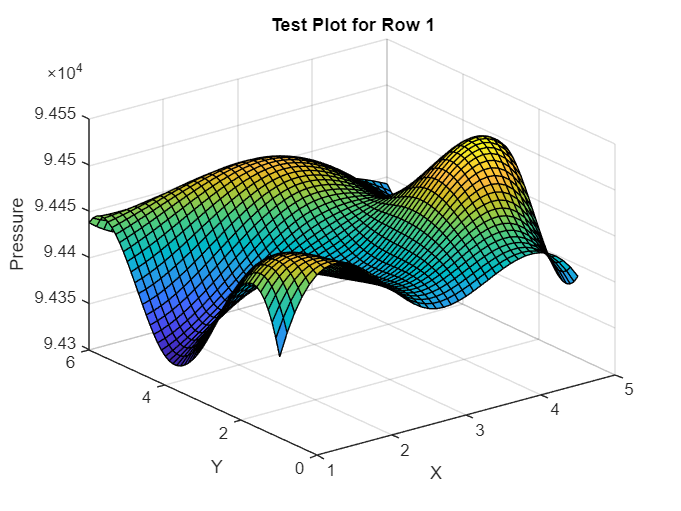

figure;
surf(Xq, Yq, interp_matrix);
title('Test Plot for Row 1');
xlabel('X');
ylabel('Y');
zlabel('Pressure');

disp(video_writer);

  VideoWriter

    General Properties:

       Filename:                 'pressure_change.avi'
       Path:                     'C:\Users\sanus\Documents\MATLAB\New folder\Loader A April Data Tables'
       FileFormat:               'avi'
       Duration:                 6.6667

    Video Properties:

       ColorChannels:            3
       Height:                   525
       Width:                    700
       FrameCount:               200
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods

